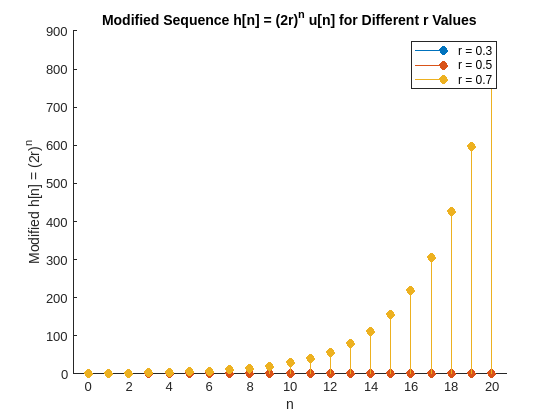

clear; close all; clc;
n = 0:20;  
h = 2.^n; 
r_values = [0.3, 0.5, 0.7];
figure;
hold on;
for i = 1:length(r_values)
    r = r_values(i);
    h_mod = (2 * r).^n;
    stem(n, h_mod, 'filled', 'DisplayName', sprintf('r = %.1f', r));
end
xlabel('n');
ylabel('Modified h[n] = (2r)^n');
title('Modified Sequence h[n] = (2r)^n u[n] for Different r Values');
legend;
hold off;

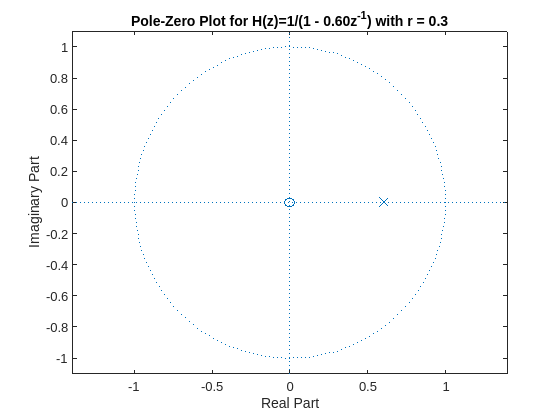


r_chosen = 0.3;
b = 1;                 
a = [1, -2 * r_chosen]; 
figure;
zplane(b, a);
title(sprintf('Pole-Zero Plot for H(z)=1/(1 - %.2fz^{-1}) with r = %.1f', 2*r_chosen, r_chosen));


[residues, poles, direct_terms] = residuez(b, a);
disp('Partial Fraction Expansion using residuez:');

Partial Fraction Expansion using residuez:


disp('Residues:');

Residues:


disp(residues);

     1



disp('Poles:');

Poles:


disp(poles);

    0.6000



disp('Direct Terms:');

Direct Terms:


disp(direct_terms);

if (2 * r_chosen < 1)
    stability = 'Stable';
else
    stability = 'Unstable';
end
fprintf('For r = %.1f, the pole is at z = %.2f.\n', r_chosen, 2*r_chosen);

For r = 0.3, the pole is at z = 0.60.


fprintf('The system is %s because |2r| = %.2f < 1.\n', stability, 2*r_chosen);

The system is Stable because |2r| = 0.60 < 1.


fprintf('The Region of Convergence (ROC) is |z| > %.2f.\n', 2*r_chosen);

The Region of Convergence (ROC) is |z| > 0.60.


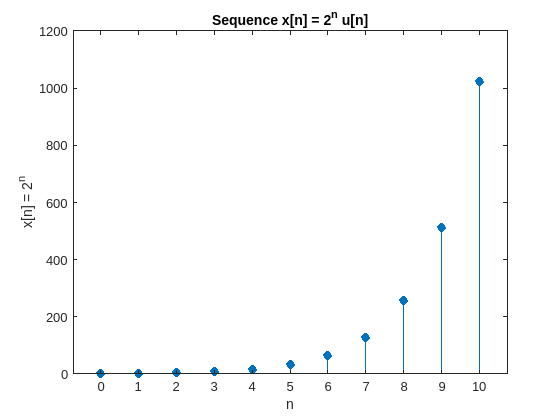

%task2:
clear; close all; clc;

n = 0:10;      
x = 2.^n;       

figure;
stem(n, x, 'filled');
xlabel('n');
ylabel('x[n] = 2^n');
title('Sequence x[n] = 2^n u[n]');


%theory: X(z) = 1 / (1 - 2*z^(-1)),  ROC: |z| > 2
%we represent X(z) in terms of z^(-1) as:
b = 1;           %num coff
a = [1, -2];     %denom coff

[residues, poles, direct_terms] = residuez(b, a);

disp('--- Partial Fraction Expansion using residuez ---');

--- Partial Fraction Expansion using residuez ---


disp('Residues:');

Residues:


disp(residues);

     1



disp('Poles:');

Poles:


disp(poles);

     2



disp('Direct Terms:');

Direct Terms:


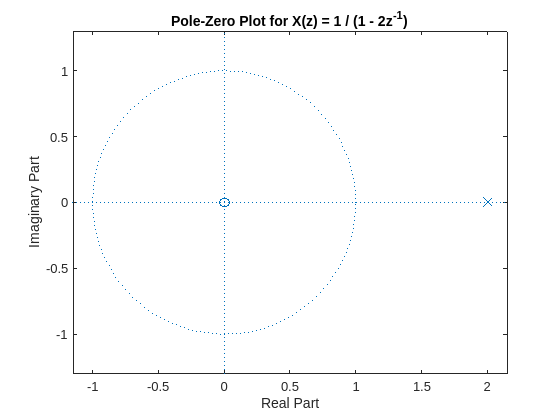

disp(direct_terms);

figure;
zplane(b, a);
title('Pole-Zero Plot for X(z) = 1 / (1 - 2z^{-1})');


%the pole is at z=2. 
%Because this is a right-sided sequence the ROC is |z| > 2.
%this ROC does NOT come inside the unit circle (|z|=1) so the system is not stable.

fprintf('\nAnalysis:\n');


Analysis:


fprintf('The pole is at z = 2.\n');

The pole is at z = 2.


fprintf('For a right-sided sequence, the ROC is |z| > 2.\n');

For a right-sided sequence, the ROC is |z| > 2.


fprintf('Since the unit circle (|z|=1) is NOT inside the ROC, the system is not stable.\n');

Since the unit circle (|z|=1) is NOT inside the ROC, the system is not stable.


%task3:
clear; close all; clc;
%X1(z) = (1 + 0.5 z^-1) / (1 - 1.5 z^-1 + 0.7 z^-2)
b1 = [1, 0.5];     
a1 = [1, -1.5, 0.7]; 

[r1, p1, d1] = residuez(b1, a1);

fprintf('=== CASE 1 ===\n');

=== CASE 1 ===


fprintf('X1(z) = (1 + 0.5 z^-1) / (1 - 1.5 z^-1 + 0.7 z^-2)\n');

X1(z) = (1 + 0.5 z^-1) / (1 - 1.5 z^-1 + 0.7 z^-2)


disp('Partial Fraction Expansion:');

Partial Fraction Expansion:


disp('Residues:'), disp(r1);

Residues:
   0.5000 - 1.6855i
   0.5000 + 1.6855i



disp('Poles:'), disp(p1);

Poles:
   0.7500 + 0.3708i
   0.7500 - 0.3708i



disp('Direct Terms:'), disp(d1);

Direct Terms:


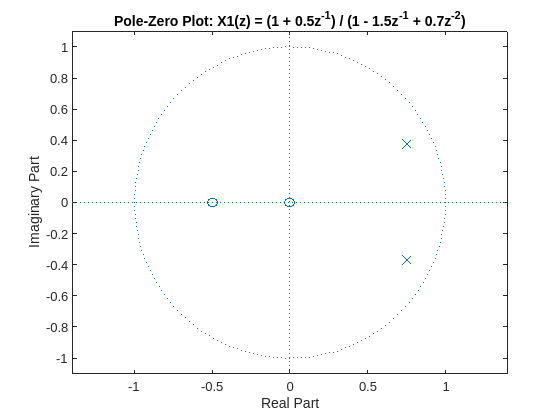


figure;
zplane(b1, a1);
title('Pole-Zero Plot: X1(z) = (1 + 0.5z^{-1}) / (1 - 1.5z^{-1} + 0.7z^{-2})');


% X2(z) = (2 + 3 z^-1) / (1 - 0.8 z^-1 - 0.2 z^-2)
b2 = [2, 3];     
a2 = [1, -0.8, -0.2];

[r2, p2, d2] = residuez(b2, a2);

fprintf('\n=== CASE 2 ===\n');


=== CASE 2 ===


fprintf('X2(z) = (2 + 3 z^-1) / (1 - 0.8 z^-1 - 0.2 z^-2)\n');

X2(z) = (2 + 3 z^-1) / (1 - 0.8 z^-1 - 0.2 z^-2)


disp('Partial Fraction Expansion:');

Partial Fraction Expansion:


disp('Residues:'), disp(r2);

Residues:
    4.1667
   -2.1667



disp('Poles:'), disp(p2);

Poles:
    1.0000
   -0.2000



disp('Direct Terms:'), disp(d2);

Direct Terms:


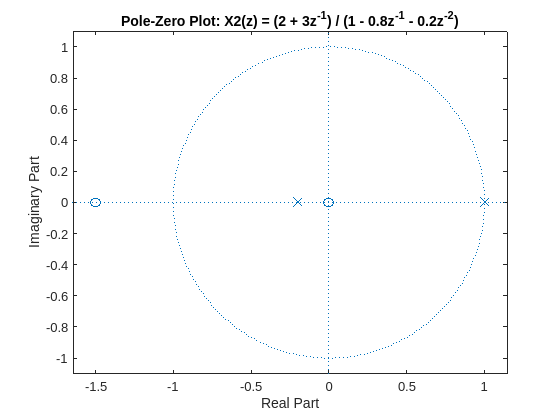


figure;
zplane(b2, a2);
title('Pole-Zero Plot: X2(z) = (2 + 3z^{-1}) / (1 - 0.8z^{-1} - 0.2z^{-2})');


%%X3(z) = (4 - z^-1 + 0.5 z^-2) / (1 + 0.3 z^-1 - 0.6 z^-2)
b3 = [4, -1, 0.5];   
a3 = [1, 0.3, -0.6]; 

[r3, p3, d3] = residuez(b3, a3);

fprintf('\n=== CASE 3 ===\n');


=== CASE 3 ===


fprintf('X3(z) = (4 - z^-1 + 0.5 z^-2) / (1 + 0.3 z^-1 - 0.6 z^-2)\n');

X3(z) = (4 - z^-1 + 0.5 z^-2) / (1 + 0.3 z^-1 - 0.6 z^-2)


disp('Partial Fraction Expansion:');

Partial Fraction Expansion:


disp('Residues:'), disp(r3);

Residues:
    3.3514
    1.4819



disp('Poles:'), disp(p3);

Poles:
   -0.9390
    0.6390



disp('Direct Terms:'), disp(d3);

Direct Terms:
   -0.8333



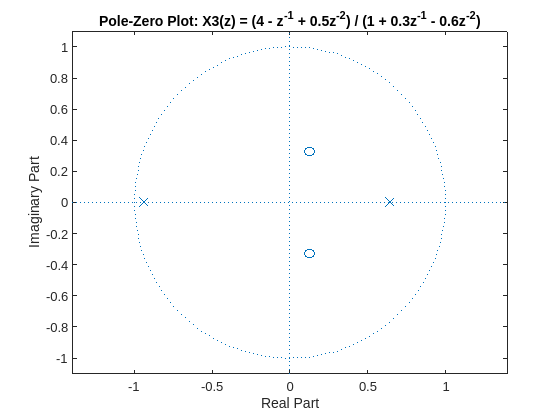


figure;
zplane(b3, a3);
title('Pole-Zero Plot: X3(z) = (4 - z^{-1} + 0.5z^{-2}) / (1 + 0.3z^{-1} - 0.6z^{-2})');

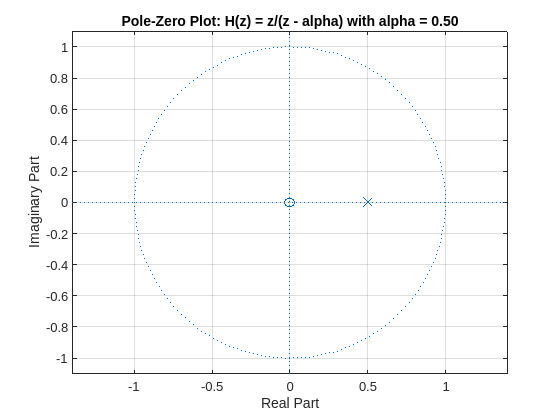

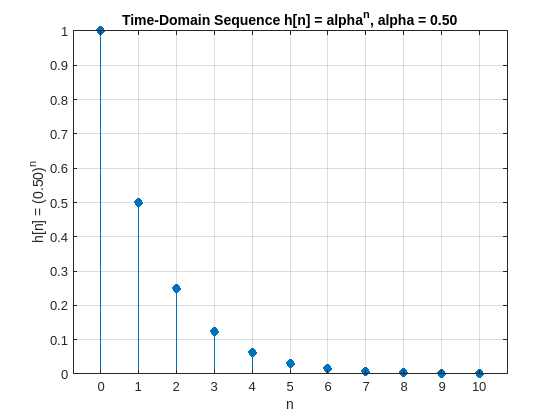

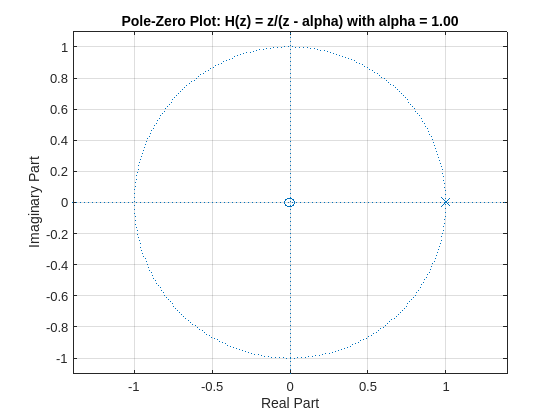

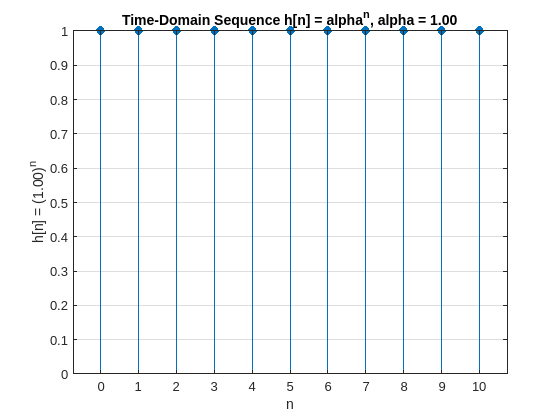

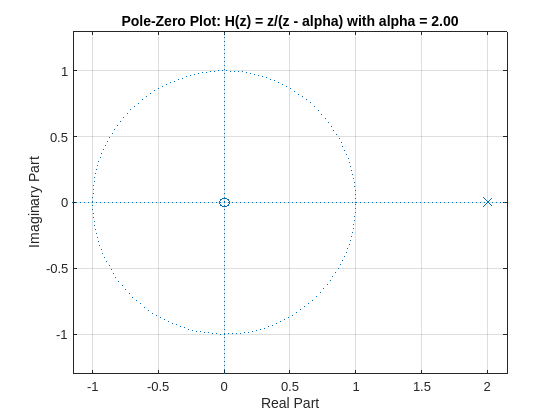

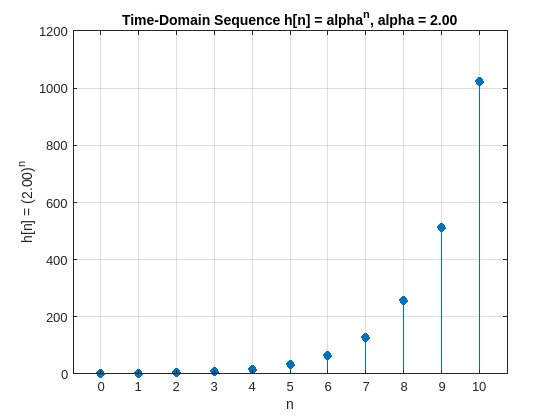

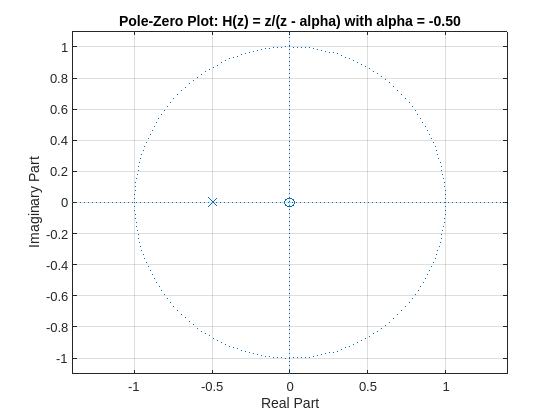

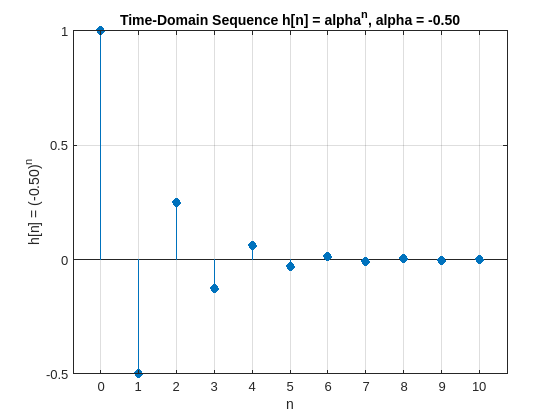

%task 4
clear; close all; clc;
alpha_values = [0.5, 1, 2, -0.5, -1, -2];
n = 0:10; 
classificationTable = cell(length(alpha_values), 6); 

for i = 1:length(alpha_values)
    alpha = alpha_values(i);
    b = 1;               %num
    a = [1, -alpha];     %denom

    figure;
    zplane(b, a);
    title(sprintf('Pole-Zero Plot: H(z) = z/(z - alpha) with alpha = %.2f', alpha));
    grid on;

    h = alpha.^n;
    figure;
    stem(n, h, 'filled');
    xlabel('n');
    ylabel(sprintf('h[n] = (%.2f)^n', alpha));
    title(sprintf('Time-Domain Sequence h[n] = alpha^n, alpha = %.2f', alpha));
    grid on;
    %Monotonic?
    %    => "Yes" if alpha > 0 (no sign changes), "No" otherwise
    if alpha > 0
        monotonic = 'Yes';
    else
        monotonic = 'No';
    end
    %Alternating?
    %    => "Yes" if alpha < 0 (sign alternates), "No" otherwise
    if alpha < 0
        alternating = 'Yes';
    else
        alternating = 'No';
    end
    %Convergent?
    %    => "Yes" if |alpha| < 1, "No" otherwise
    if abs(alpha) < 1
        convergent = 'Yes';
    else
        convergent = 'No';
    end
    %Constant?
    %    => "Yes" if alpha == 1, "No" otherwise
    if alpha == 1
        constant = 'Yes';
    else
        constant = 'No';
    end
    %Divergent?
    %    => "Yes" if |alpha| > 1 or alpha == -1, "No" otherwise
    %    (alpha = -1 oscillates between +1/-1, not convergent => "Yes" for divergent)
    if (abs(alpha) > 1) || (alpha == -1)
        divergent = 'Yes';
    else
        divergent = 'No';
    end

    classificationTable{i,1} = alpha;         % alpha value
    classificationTable{i,2} = monotonic;     % "Yes"/"No"
    classificationTable{i,3} = alternating;   % "Yes"/"No"
    classificationTable{i,4} = convergent;    % "Yes"/"No"
    classificationTable{i,5} = constant;      % "Yes"/"No"
    classificationTable{i,6} = divergent;     % "Yes"/"No"
end


disp('============================================================');

disp('          Classification for H(z) = z/(z - alpha)');

          Classification for H(z) = z/(z - alpha)


disp('============================================================');

disp(' alpha   Monotonic  Alternating  Convergent  Constant  Divergent');

 alpha   Monotonic  Alternating  Convergent  Constant  Divergent


disp('------------------------------------------------------------');

------------------------------------------------------------



for i = 1:length(alpha_values)
    alpha  = classificationTable{i,1};
    mono   = classificationTable{i,2};
    alt    = classificationTable{i,3};
    conv   = classificationTable{i,4};
    cst    = classificationTable{i,5};
    divg   = classificationTable{i,6};
    fprintf(' %5.2f    %7s     %7s       %7s     %7s     %7s\n', ...
            alpha, mono, alt, conv, cst, divg);
end

  0.50        Yes          No           Yes          No          No
  1.00        Yes          No            No         Yes          No
  2.00        Yes          No            No          No         Yes
 -0.50         No         Yes           Yes          No          No
 -1.00         No         Yes            No          No         Yes
 -2.00         No         Yes            No          No         Yes



disp('============================================================');

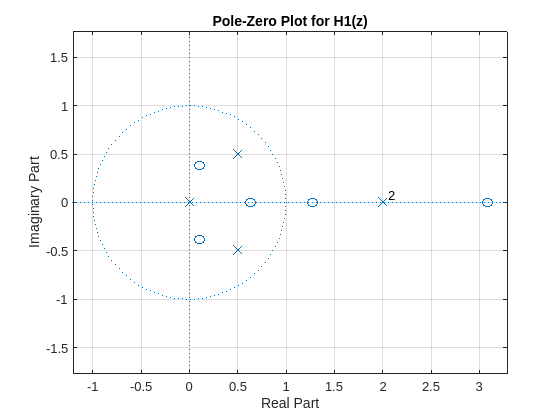

% Task 6
clear; close all; clc;

% H1(z) = (5 - 26z^-1 + 39.5z^-2 - 23.5z^-3 + 8z^-4 - 2z^-5)
%         / (1 - 5z^-1 + 8.5z^-2 - 6z^-3 + 2z^-4)
b1 = [5, -26, 39.5, -23.5, 8, -2];
a1 = [1, -5, 8.5, -6, 2];

figure;
zplane(b1, a1);
title('Pole-Zero Plot for H1(z)');
grid on;

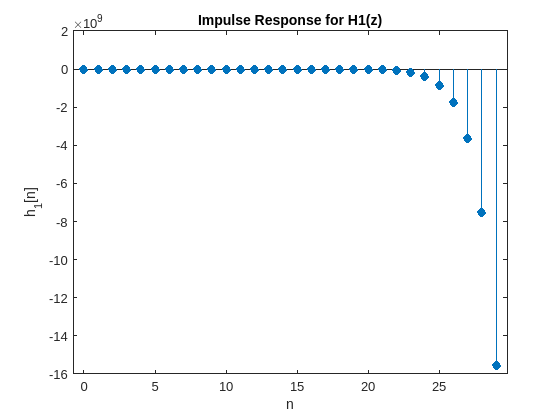


[imp1, n1] = impz(b1, a1, 30);
figure;
stem(n1, imp1, 'filled');
xlabel('n'); ylabel('h_1[n]');
title('Impulse Response for H1(z)');


poles1 = roots(a1);
if all(abs(poles1) < 1)
    fprintf('H1(z): Stable => all poles inside unit circle.\n');
    fprintf('Impulse response converges.\n');
else
    fprintf('H1(z): Unstable => some pole(s) >= 1 in magnitude.\n');
    fprintf('Impulse response diverges.\n');
end

H1(z): Unstable => some pole(s) >= 1 in magnitude.


Impulse response diverges.


fprintf('-------------------------------------------------------\n\n');

-------------------------------------------------------



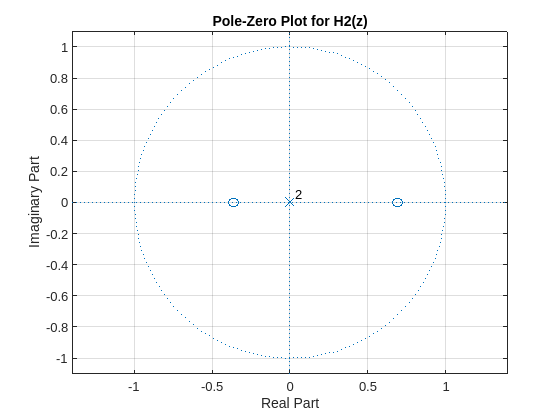



%H2(z) = (3z^2 - z - 0.75)/z^2,  => 3 - z^-1 - 0.75z^-2
%ROC: |z| > 0.5 
b2 = [3, -1, -0.75];
a2 = 1;

figure;
zplane(b2, a2);
title('Pole-Zero Plot for H2(z)');
grid on;

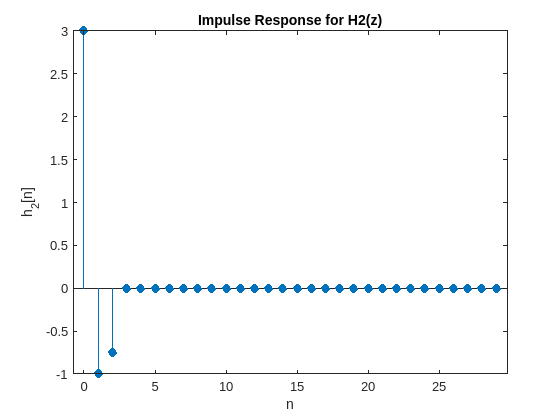


[imp2, n2] = impz(b2, a2, 30);
figure;
stem(n2, imp2, 'filled');
xlabel('n'); ylabel('h_2[n]');
title('Impulse Response for H2(z)');


fprintf('H2(z): FIR => poles at z=0 => inside unit circle => stable.\n');

H2(z): FIR => poles at z=0 => inside unit circle => stable.


fprintf('Impulse response is finite in length => convergent.\n');

Impulse response is finite in length => convergent.


fprintf('-------------------------------------------------------\n\n');

-------------------------------------------------------



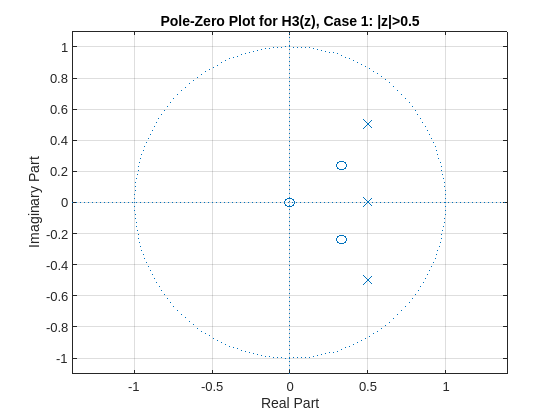


% H3(z)=(3 - 2z^-1 + 0.5z^-2) / (1 - 1.5z^-1 + z^-2 - 0.25z^-3)
% Case 1: ROC: |z| > 0.5
% Case 2: ROC: |z| > 2 
b3 = [3, -2, 0.5];
a3 = [1, -1.5, 1, -0.25];

%Case 1
figure;
zplane(b3, a3);
title('Pole-Zero Plot for H3(z), Case 1: |z|>0.5');
grid on;

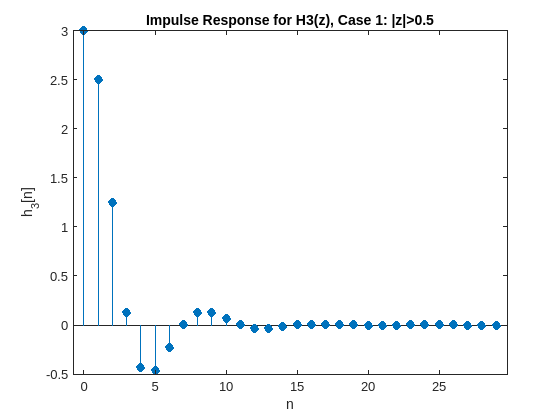


[imp3_case1, n3] = impz(b3, a3, 30);
figure;
stem(n3, imp3_case1, 'filled');
xlabel('n'); ylabel('h_3[n]');
title('Impulse Response for H3(z), Case 1: |z|>0.5');


poles3 = roots(a3);
if all(abs(poles3) < 1)
    fprintf('H3(z), Case 1: Poles <1 => stable => convergent.\n');
else
    fprintf('H3(z), Case 1: Unstable => diverges.\n');
end

H3(z), Case 1: Poles <1 => stable => convergent.


fprintf('(Assuming a right-sided system, ROC is outside the largest pole => |z|>0.5.)\n\n');

(Assuming a right-sided system, ROC is outside the largest pole => |z|>0.5.)



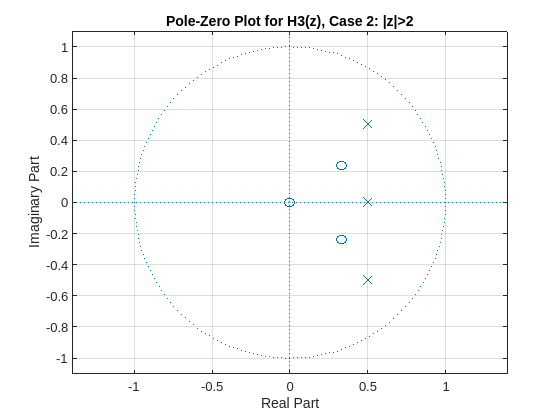


%Case 2
figure;
zplane(b3, a3);
title('Pole-Zero Plot for H3(z), Case 2: |z|>2');
grid on;


fprintf('H3(z), Case 2: If we force ROC |z|>2, but largest pole is <2,\n');

H3(z), Case 2: If we force ROC |z|>2, but largest pole is <2,


fprintf('that implies a non-causal (left-sided) realization.\n');

that implies a non-causal (left-sided) realization.


fprintf('Impulse response for a right-sided system is still the same as Case 1.\n');

Impulse response for a right-sided system is still the same as Case 1.


fprintf('-------------------------------------------------------\n\n');

-------------------------------------------------------



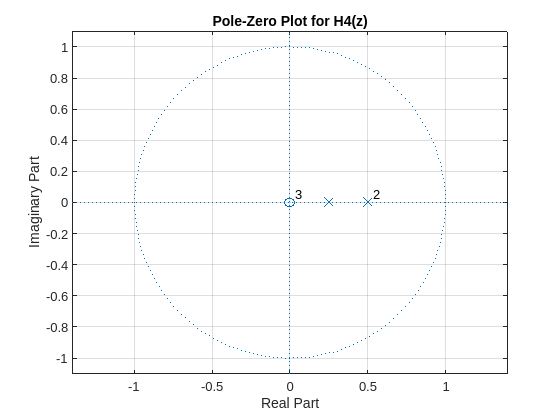



% H4(z) = 1 / (1 - 1.25z^-1 + 0.5z^-2 - 0.0625z^-3)
b4 = 1;
a4 = [1, -1.25, 0.5, -0.0625];

figure;
zplane(b4, a4);
title('Pole-Zero Plot for H4(z)');
grid on;

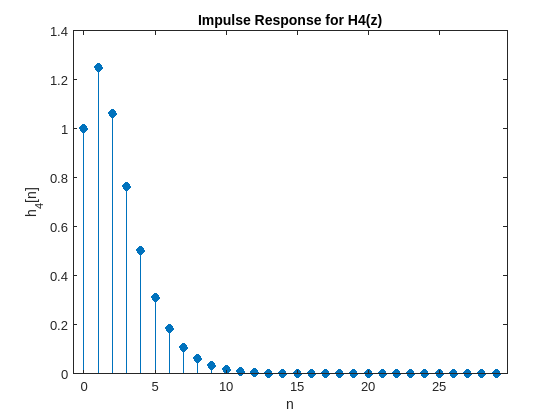


[imp4, n4] = impz(b4, a4, 30);
figure;
stem(n4, imp4, 'filled');
xlabel('n'); ylabel('h_4[n]');
title('Impulse Response for H4(z)');


poles4 = roots(a4);
if all(abs(poles4) < 1)
    fprintf('H4(z): All poles inside unit circle => stable.\n');
else
    fprintf('H4(z): Some pole(s) >=1 => unstable.\n');
end

H4(z): All poles inside unit circle => stable.


fprintf('-------------------------------------------------------\n\n');

-------------------------------------------------------



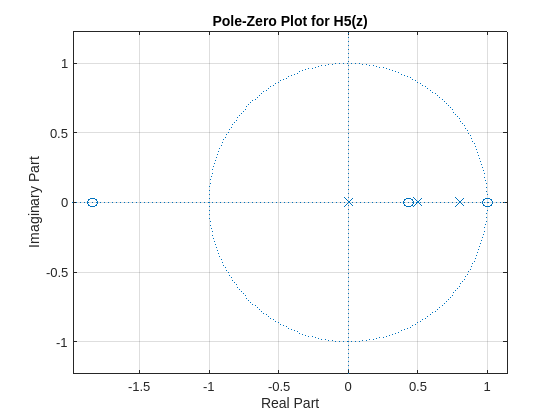


% H5(z)=(1 + 0.4z^-1 - 2.2z^-2 + 0.8z^-3) / (1 - 1.3z^-1 + 0.4z^-2)
b5 = [1, 0.4, -2.2, 0.8];
a5 = [1, -1.3, 0.4];

figure;
zplane(b5, a5);
title('Pole-Zero Plot for H5(z)');
grid on;

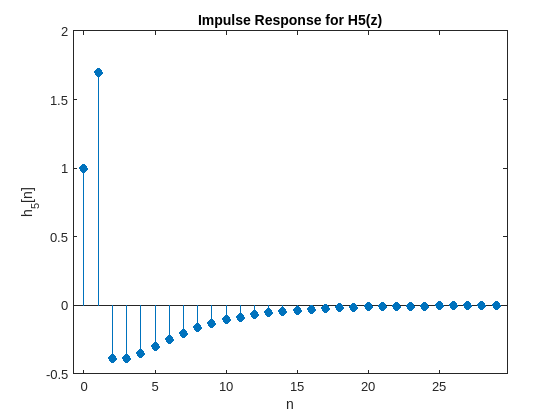


[imp5, n5] = impz(b5, a5, 30);
figure;
stem(n5, imp5, 'filled');
xlabel('n'); ylabel('h_5[n]');
title('Impulse Response for H5(z)');


poles5 = roots(a5);
if all(abs(poles5) < 1)
    fprintf('H5(z): Poles inside unit circle => stable => convergent.\n');
else
    fprintf('H5(z): Unstable => diverges.\n');
end

H5(z): Poles inside unit circle => stable => convergent.


% Task 7, Problem 1:
clear; close all; clc;
syms z n real
Hz = (z + 0.5) / (z + 0.25);  
h_sym = iztrans(Hz, z, n);

disp('--- Symbolic Transfer Function H(z) ---');

--- Symbolic Transfer Function H(z) ---


disp(Hz);

$$\frac{z+\frac{1}{2}}{z+\frac{1}{4}}$$

disp(' ');


disp('--- Symbolic Impulse Response h[n] ---');

--- Symbolic Impulse Response h[n] ---


disp(h_sym);

$$2\,\delta_{n,0}-{\left(-\frac{1}{4}\right)}^{n}$$

disp(' ');


disp('--- First 5 Samples of h[n] from Symbolic Math ---');

--- First 5 Samples of h[n] from Symbolic Math ---


for k = 0:4
    val_k = subs(h_sym, n, k);
    val_num = double(val_k);
    fprintf('h[%d] = %f\n', k, val_num);
end

h[0] = 1.000000
h[1] = 0.250000
h[2] = -0.062500
h[3] = 0.015625
h[4] = -0.003906


disp(' ');

b = [1, 0.5];
a = [1, 0.25];
N = 5;
impulse_input = [1, zeros(1, N-1)];
h_filter = filter(b, a, impulse_input);

disp('--- Verification via filter() for first 5 samples ---');

--- Verification via filter() for first 5 samples ---


for k = 0:4
    fprintf('h[%d] = %f\n', k, h_filter(k+1));
end

h[0] = 1.000000
h[1] = 0.250000
h[2] = -0.062500
h[3] = 0.015625
h[4] = -0.003906


% Task 7, Problem 2:
clear; close all; clc;
syms z n real
Hz = (z^2 + 0.5)/(z^2 + 0.25);
disp('--- Symbolic Transfer Function H(z) ---');

--- Symbolic Transfer Function H(z) ---


disp(Hz);

$$\frac{z^{2}+\frac{1}{2}}{z^{2}+\frac{1}{4}}$$


h_sym = iztrans(Hz, z, n);
disp('--- Symbolic Impulse Response h[n] ---');

--- Symbolic Impulse Response h[n] ---


disp(h_sym);

$$2\,\delta_{n,0}+\frac{{\left(-\frac{1}{2}\,\mathrm{i}\right)}^{n-1}\,\mathrm{i}}{4}-\frac{{\left(\frac{1}{2}\,\mathrm{i}\right)}^{n-1}\,\mathrm{i}}{4}$$


disp('--- First 6 Samples of h[n] (Symbolic) ---');

--- First 6 Samples of h[n] (Symbolic) ---


for k = 0:5
    val_k = subs(h_sym, n, k);
    val_num = double(val_k);
    fprintf('h[%d] = %f\n', k, val_num);
end

h[0] = 1.000000
h[1] = 0.000000
h[2] = 0.250000
h[3] = 0.000000
h[4] = -0.062500
h[5] = 0.000000




b = [1, 0, 0.5];
a = [1, 0, 0.25];

N = 6;
impulse_input = [1, zeros(1, N-1)];
h_filter = filter(b, a, impulse_input);

disp('--- Numerical Impulse Response via filter() ---');

--- Numerical Impulse Response via filter() ---


for k = 0:5
    fprintf('h[%d] = %f\n', k, h_filter(k+1));
end

h[0] = 1.000000
h[1] = 0.000000
h[2] = 0.250000
h[3] = 0.000000
h[4] = -0.062500
h[5] = 0.000000




disp(' ');

disp('--- Part (b): Find x[n] if y[n] = (1/2)^n u[n] ---');

--- Part (b): Find x[n] if y[n] = (1/2)^n u[n] ---



Yz = z/(z - 0.5);              
Xz_simpl = simplify(Yz / Hz);    

disp('--- Symbolic X(z) that yields y[n] = (1/2)^n ---');

--- Symbolic X(z) that yields y[n] = (1/2)^n ---


disp(Xz_simpl);

$$\frac{z\,\left(z^{2}+\frac{1}{4}\right)}{\left(z^{2}+\frac{1}{2}\right)\,\left(z-\frac{1}{2}\right)}$$


x_sym = iztrans(Xz_simpl, z, n);
disp('--- Symbolic x[n] ---');

--- Symbolic x[n] ---


disp(x_sym);

$$\frac{2\,{\left(\frac{1}{2}\right)}^{n}}{3}-\frac{\sqrt{2}\,\left(-1+\frac{\sqrt{2}\,\mathrm{i}}{2}\right)\,{\left(\frac{\sqrt{2}\,\mathrm{i}}{2}\right)}^{n-1}\,\mathrm{i}}{12}-\frac{\sqrt{2}\,\left(1+\frac{\sqrt{2}\,\mathrm{i}}{2}\right)\,{\left(-\frac{\sqrt{2}\,\mathrm{i}}{2}\right)}^{n-1}\,\mathrm{i}}{12}$$


disp('--- First 6 Samples of x[n] (Symbolic) ---');

--- First 6 Samples of x[n] (Symbolic) ---


for k = 0:5
    x_val_k = subs(x_sym, n, k);
    x_val_num = double(x_val_k);
    fprintf('x[%d] = %s  (%.4f)\n', k, string(x_val_k), x_val_num);
end

x[0] = 1  (1.0000)
x[1] = 1/3 - (2^(1/2)*((2^(1/2)*1i)/2 + 1)*1i)/12 - (2^(1/2)*((2^(1/2)*1i)/2 - 1)*1i)/12  (0.5000)
x[2] = 0  (0.0000)
x[3] = (2^(1/2)*((2^(1/2)*1i)/2 - 1)*1i)/24 + (2^(1/2)*((2^(1/2)*1i)/2 + 1)*1i)/24 + 1/12  (0.0000)
x[4] = 1/8  (0.1250)
x[5] = 1/48 - (2^(1/2)*((2^(1/2)*1i)/2 + 1)*1i)/48 - (2^(1/2)*((2^(1/2)*1i)/2 - 1)*1i)/48  (0.0625)
